clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20220805\IBM_bounded_sx=2_sy=512_nbins=12_nmax=2_del=0.001_b=10_p=1.mat')
%load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20220927_test\IBM_bounded_sx=2_sy=512_nbins=12_nmax=0_del=0.001_b=10_p=1.mat')
saveto_filepath = 'C:/Users/eschlatter/Dropbox/DispersalEvolution/output_simulations/20220805';

#### Survival

% figure
% clf
% t1 = tiledlayout(1,2);
% title(t1,sprintf('Larval survival over time, nmax = %g',nmax));
% % number of larvae over time
% nexttile
% plot(fitness)
% title('Number of Larvae Over Time')
% legend('hatched','dispersed','navigated')
% 
% % fitness over time
% % (fitness = fraction of larvae that survive after dispersal and navigation)
% nexttile
% plot(1:G,fitness(:,3)./fitness(:,1))
% title('Fitness over time')
% xlabel('Generation')
% ylabel('Fraction of larve surviving dispersal and navigation')
% %saveas(t1, sprintf('%s/survival_nmax=%g.jpg',saveto_filepath,nmax))
% figure
% clf
% % fitness over time
% % (fitness = fraction of larvae that survive after dispersal and navigation)
% plot(1:G,fitness(:,3)./fitness(:,1))
% title(sprintf('Larval survival over time, nmax = %g',nmax))
% xlabel('Generation')
% ylabel('Fraction of larve surviving dispersal and navigation')
% saveas(gcf, sprintf('%s/survival1_nmax=%g.jpg',saveto_filepath,nmax))

#### Kernels over time

figure
clf
t2=tiledlayout(2,2);
title(t2,sprintf('Kernels, nmax = %g',nmax));
xlabel(t2,'Generation');
ylabel(t2,'Probability or Number');

% plot the evolved dispersal bin values across generations

nexttile
hold on
errorbar(dtime_avg,dtime_std)
axis([0 G 0 1.1])
title('Displacement Strategy Evolution')
xlabel('Generation')
ylabel('Probability')
hold off

% plot the evolving displacement kernel across generations
nexttile
plot(kernel_displacement)
title('Displacement Kernel')

% plot the evolving dispersal kernel across generations
nexttile
plot(kernel_dispersal)
title('Dispersal Kernel')

% plot the evolving recruitment kernel across generations
nexttile
plot(kernel_recruitment)
title('Recruitment Kernel')

leg2 = legend(string((1:nbins)-1));
leg2.Layout.Tile = 'east';

saveas(t2, sprintf('%s/KernsOverTime_nmax=%g.jpg',saveto_filepath,nmax))

#### Kernels at the end

figure
gens = 100;
t3 = tiledlayout(3,1);
title(t3,sprintf('Kernels, nmax = %g, last %g generations',nmax,gens))
xlabel(t3,'Distance')
ylabel(t3,'Probability')

% Displacement kernel
nexttile
end_displacement = kernel_displacement((size(kernel_displacement,1)-gens):size(kernel_displacement,1),:); %last rows (generations)
scale_end_displacement = end_displacement./sum(end_displacement,2); %scaled by total number of larvae each generation
median_end_displacement = median(scale_end_displacement,1);
std_end_displacement = std(scale_end_displacement,1);
bar(0:(size(kernel_displacement,2)-1),median_end_displacement)
hold on
er = errorbar(0:(size(kernel_displacement,2)-1),median_end_displacement,std_end_displacement);
er.LineStyle = 'none';
er.Color = [0 0 0];
title('ESS Displacement Kernel, nmax=2')
xlabel('Distance')
ylabel('Probability')
ylim([0 1])
hold off

hold on
bar(0:11,[0.33 0.33 0.33 zeros(1,9)])
title('Starting Displacement Kernel, nmax=1')
xlabel('Distance')
ylabel('Probability')
ylim([0 1])
hold off

% Dispersal kernel
nexttile
end_dispersal = kernel_dispersal((size(kernel_dispersal,1)-gens):size(kernel_dispersal,1),:); %last rows (generations)
scale_end_dispersal = end_dispersal./sum(end_dispersal,2); %scaled by total number of larvae each generation
median_end_dispersal = median(scale_end_dispersal,1);
std_end_dispersal = std(scale_end_dispersal,1);
bar(0:(size(kernel_dispersal,2)-1),median_end_dispersal)
hold on
er = errorbar(0:(size(kernel_dispersal,2)-1),median_end_dispersal,std_end_dispersal);
er.LineStyle = 'none';
er.Color = [0 0 0];
title('Dispersal')
hold off

% Recruitment kernel
nexttile
end_recruitment = kernel_recruitment((size(kernel_recruitment,1)-gens):size(kernel_recruitment,1),:); %last rows (generations)
scale_end_recruitment = end_recruitment./sum(end_recruitment,2); %scaled by total number of larvae each generation
median_end_recruitment = median(scale_end_recruitment,1);
std_end_recruitment = std(scale_end_recruitment,1);
bar(0:(size(kernel_recruitment,2)-1),median_end_recruitment)
hold on
er = errorbar(0:(size(kernel_recruitment,2)-1),median_end_recruitment,std_end_recruitment);
er.LineStyle = 'none';
er.Color = [0 0 0];
title('Recruitment')
hold off

saveas(t3, sprintf('%s/KernsEnd_nmax=%g.jpg',saveto_filepath,nmax))

#### Measures of fitness

Four measures of fitness, encompassing increasingly more of the lifespan:

- A larva's probability of surviving navigation

- A larva's probability of successfully recruiting

- Number of offspring per parent that survive navigation

- Number of successfully recruiting offspring per parent

[Note that 3 and 4 are offset by a generation -- i.e., in these plots, the values of fitness measures 3 and 4 plotted in generation n apply to generation n-1. Vs. the values of fitness measures 1 and 2 plotted in generation n, which  apply to generation n. Could offset the plots by a year to correct for this, but for 100000 generations it doesn't really matter.]

Probability of surviving navigation

figure
clf
% fraction of larvae that survive after dispersal and navigation)
plot(1:G,fitness(:,3)./fitness(:,1))
title(sprintf('Larval survival, nmax = %g',nmax))
xlabel('Generation')
ylabel('Fraction of larve surviving dispersal and navigation')

Probability of successful recruitment

[just 10%-ish of the above figure -- a little more, because some larvae didn't survive dispersal so they're not competing here]

Per-parent survival

% plot # of offspring that successfully disperse
figure
clf
mean_parent_surv_dispersal = mean(parent_surv_dispersal);
sd_parent_surv_dispersal = std(parent_surv_dispersal);
errorbar(mean_parent_surv_dispersal,sd_parent_surv_dispersal)
title(sprintf('Offspring surviving dispersal per parent, nmax = %g',nmax));
xlabel('Generation')
ylabel('Successfully dispersing offspring per parent (mean+/-sd)')

Per-parent recruitment


% plot # of offspring that successfully recruit
figure
clf
mean_parent_surv_recruitment = mean(parent_surv_recruitment);
sd_parent_surv_recruitment = std(parent_surv_recruitment);
errorbar(mean_parent_surv_recruitment,sd_parent_surv_recruitment)
title(sprintf('Successful recruits per parent, nmax = %g',nmax));
xlabel('Generation')
ylabel('Successfully recruiting offspring per parent (mean+/-sd)')

### Survival-recruitment tradeoff?

% figure
% clf
% ylim([0 10])
% xlim([0 10])
% xlabel('number of larvae surviving dispersal')
% ylabel('number of larvae surviving recruitment')
% hold on
% for i=1:100000
%     f = fit(parent_surv_dispersal(:,100*i),parent_surv_recruitment(:,1000*i),'poly2');
%     plot(f)
%     legend('off')
%     drawnow
% end
% hold off


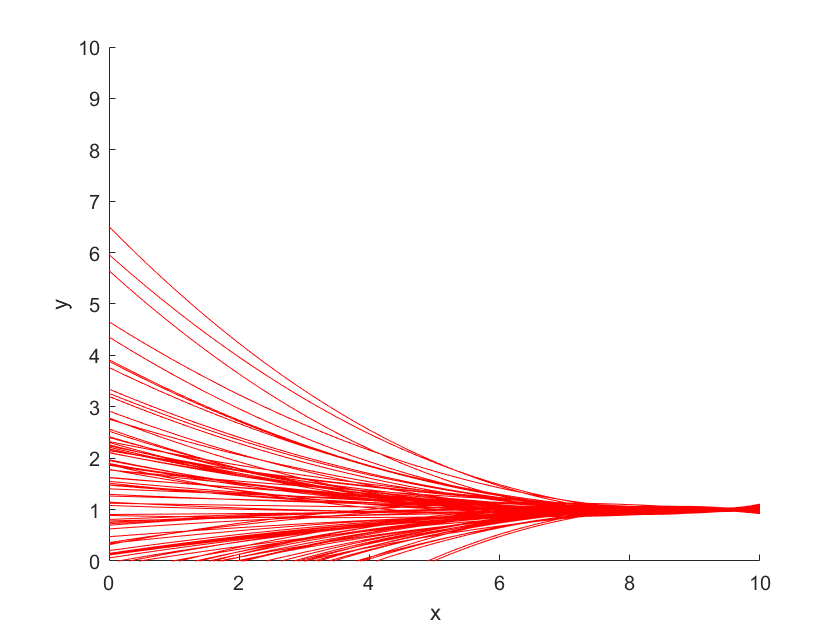

Index in position 2 exceeds array bounds. Index must not exceed 100000.

figure
clf
ylim([0 1])
xlim([0 10])
hold on
for i=1:100000
    dispersers = parent_surv_dispersal(:,i);
    recruiters = parent_surv_recruitment(:,i);

    %deal with the zeros

    f=fit(parent_surv_dispersal(:,i),parent_surv_recruitment(:,i)./parent_surv_dispersal(:,i),'poly2');
    plot(f,parent_surv_dispersal(:,i),parent_surv_recruitment(:,i)./parent_surv_dispersal(:,i))
    legend('off')
    drawnow
end
hold off


%scatter(parent_surv_dispersal(:,1),parent_surv_recruitment(:,1)./parent_surv_dispersal(:,1),'jitter','on','jitterAmount',0.1)

### Displacement-Fitness covariance

figure
clf
ylim([0 6])
xlim([0.48 0.55])
hold on

for i=2:G
    f = fit(parent_kernel_mean(:,i),parent_surv_recruitment(:,i),'poly2');
    plot(f,parent_kernel_mean(:,i),parent_surv_recruitment(:,i))
    legend('off')
    drawnow
end

hold off